%% ============================================================
% SINGLE PHOTON CAMERA REAL DATA RECONSTRUCTION
% Mirror Position -> SPC Frame -> Background Correction -> Richardson-Lucy
% ============================================================

clear; clc; close all

%% ============================================================
% READ PHOTON COUNT CSV
% ============================================================

folder = '\\userfs\bh1308\w2k\Desktop\Single Photon Camera\CSV';

filename = uigetfile(fullfile(folder,'*.csv'), ...
    'Select Photon Scan File');

data = readtable(fullfile(folder, filename));

%% ============================================================
% EXTRACT DATA
% ============================================================

mirrorX = data.X;
mirrorY = data.Y;
Counts  = data.Count;

%% ============================================================
% SCAN PARAMETERS
% ============================================================

Nx = 41;
Ny = 41;

%% ============================================================
% CONVERT MIRROR POSITIONS TO PIXEL POSITIONS
% ============================================================

x_grid = linspace(min(mirrorX), max(mirrorX), Nx);
y_grid = linspace(min(mirrorY), max(mirrorY), Ny);

SPC_counts = zeros(Ny,Nx);
SPC_visits = zeros(Ny,Nx);

for k = 1:length(Counts)

    [~,x_index] = min(abs(x_grid - mirrorX(k)));
    [~,y_index] = min(abs(y_grid - mirrorY(k)));

    % Accumulate counts
    SPC_counts(y_index,x_index) = SPC_counts(y_index,x_index) + Counts(k);

    % Count how many measurements landed here
    SPC_visits(y_index,x_index) = SPC_visits(y_index,x_index) + 1;

end

% Calculate average where measurements exist
SPC_frame = zeros(Ny,Nx);

valid = SPC_visits > 0;

SPC_frame(valid) = SPC_counts(valid) ./ SPC_visits(valid);

%% ============================================================
% SAVE RAW IMAGE
% ============================================================

SPC_frame_raw = SPC_frame;

%% ============================================================
% CALCULATE BACKGROUND THRESHOLD
% ============================================================
%% calculated using median instead as bright counts affected mean too much

backgroundCounts = Counts;

backgroundmedian = median(backgroundCounts);
sigma = std(backgroundCounts);

k = -0.1;                         % Number of standard deviations

threshold = backgroundmedian + k*sigma;

fprintf('Background Median = %.2f\n',backgroundmedian);

Background Median = 65.00


fprintf('Background SD   = %.2f\n',sigma);

Background SD   = 32.69


fprintf('Threshold       = %.2f\n',threshold);

Threshold       = 61.73


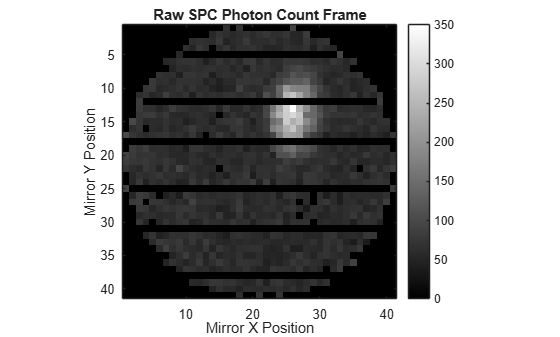


%% ============================================================
% BACKGROUND CORRECTION
% ============================================================

SPC_frame_corrected = SPC_frame_raw;

% Subtract threshold

SPC_frame_corrected = max(SPC_frame_raw - threshold, 0);

Photon_image = SPC_frame_corrected;

%% ============================================================
% DISPLAY RAW IMAGE
% ============================================================

figure

imagesc(rot90(SPC_frame_raw))

axis image
axis ij
colormap(gray)
colorbar

title('Raw SPC Photon Count Frame')

xlabel('Mirror X Position')
ylabel('Mirror Y Position')

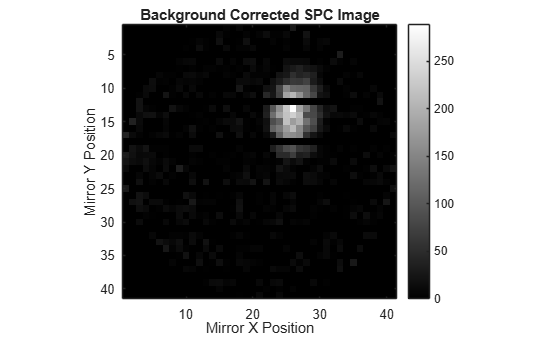


%% ============================================================
% DISPLAY BACKGROUND CORRECTED IMAGE
% ============================================================

figure

imagesc(rot90(Photon_image))

axis image
axis ij
colormap(gray)
colorbar

title('Background Corrected SPC Image')

xlabel('Mirror X Position')
ylabel('Mirror Y Position')

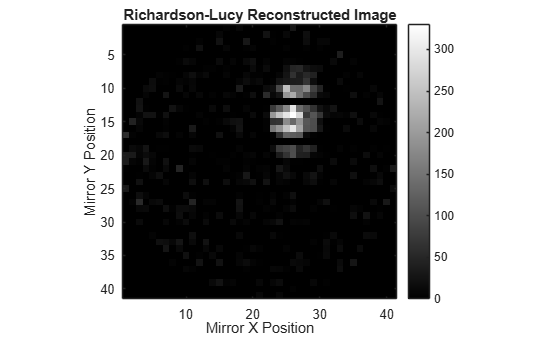


%% ============================================================
% PSF MODEL
% ============================================================

PSF_SIGMA = 0.7;

PSF = fspecial('gaussian',[7 7],PSF_SIGMA);


%% ============================================================
% RICHARDSON-LUCY DECONVOLUTION
% ============================================================

iterations = 5;

RL_image = deconvlucy(Photon_image, PSF, iterations);

%% ============================================================
% DISPLAY RICHARDSON-LUCY IMAGE
% ============================================================

figure

imagesc(rot90(RL_image))

axis image
axis ij
colormap(gray)
colorbar

title('Richardson-Lucy Reconstructed Image')

xlabel('Mirror X Position')
ylabel('Mirror Y Position')